alpha


PARTICIPANT ID: 001
PARTICIPANT ID: 002
PARTICIPANT ID: 003
PARTICIPANT ID: 004
PARTICIPANT ID: 005
PARTICIPANT ID: 006
PARTICIPANT ID: 007
PARTICIPANT ID: 008
PARTICIPANT ID: 009
PARTICIPANT ID: 010
PARTICIPANT ID: 011
PARTICIPANT ID: 012
PARTICIPANT ID: 013
PARTICIPANT ID: 015
PARTICIPANT ID: 017
PARTICIPANT ID: 019
PARTICIPANT ID: 021


fc_pre_group_avg:


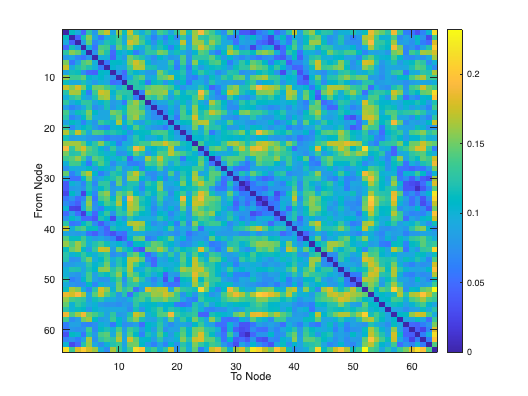

fc_post_group_avg:


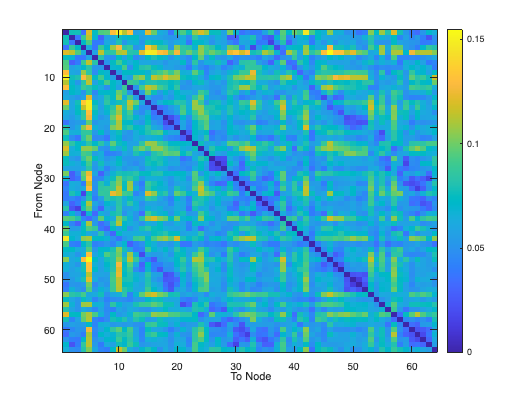

fc_diff_conn_mat:


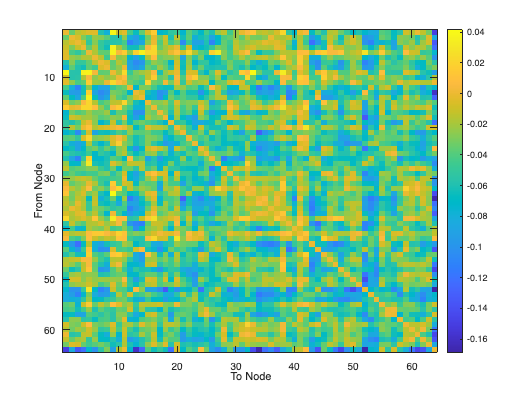

% Pre vs post 
% naming convention for reference: 
%   "FIBROP001_DD1_BL_clean.mat" --> participant 1; dosing day 1 (placebo);
%   baseline

% general variables
DATA_DIR = "../EEG_data";
SAVE_DIR = "../saved_data";
TEXT_PRE = "DD1_BL";
TEXT_POST = "DD2_90";
RUN_FROM_BEGINNING = false;
PARTICIPANTS_TO_INCLUDE = [1:13, 15, 17, 19, 21]; % [1:15, 17:21]; % [1:15, 17:21];
FREQ_BANDS = {'theta', 'alpha', 'low_beta', 'high_beta', 'gamma'};
FC_METHOD = 'icoh'; % options = {'icoh', 'corr', 'granger'}
ALL_ELECTRODES = load(sprintf("%s/FIBROP001_%s_clean.mat", DATA_DIR, TEXT_PRE)).allart.channel; % using default first file as an example, just to get all electrode labels
NUM_ELECTRODES = length(ALL_ELECTRODES);
ELECTRODE_ORGANIZATIONS = categorizeElectrodes(ALL_ELECTRODES); % assumes all electrode labels start off in the same order

for freq_band_idx = 2:2 % 1:5 
    % [CONSIDER NOT LOOPING THROUGH AND JUST DOING ONE FREQUENCY BAND
    % AT A TIME!!]
    disp(char(FREQ_BANDS(freq_band_idx)));
    freq_band = char(FREQ_BANDS(freq_band_idx));

    % group level --> change this to be alphabetical + by region maybe
    fc_pre_group_all_chan = zeros(NUM_ELECTRODES, NUM_ELECTRODES, length(PARTICIPANTS_TO_INCLUDE));
    fc_post_group_all_chan = zeros(NUM_ELECTRODES, NUM_ELECTRODES, length(PARTICIPANTS_TO_INCLUDE)); 
    
    idx_count = 1;
    % Loop through all participants
    for participant_id = PARTICIPANTS_TO_INCLUDE
        disp(sprintf("PARTICIPANT ID: %03d", participant_id));
        % idx_count = get the index of participant_id within the
        % PARTICIPANTS_TO_INCLUDE array
        
        if RUN_FROM_BEGINNING == true
            filename_pre = sprintf("%s/FIBROP%03d_%s_clean.mat", DATA_DIR, participant_id, TEXT_PRE);
            filename_post = sprintf("%s/FIBROP%03d_%s_clean.mat", DATA_DIR, participant_id, TEXT_POST);
    
            % load and preprocess data
            % function parameters --> load_data(filename (string), CAR_bool (boolean))
            data_pre = loadData(filename_pre, true);
            data_post = loadData(filename_post, true);
    
            % find intersecting channels between data (NOT SURE IF THIS IS
            % NECESSARY)
            INT_CHAN_LABELS = cellstr(intersect(string(data_pre.label), string(data_post.label)));
    
            % run FC analysis individually 
            % function parameters --> fc_analysis(data (struct), FC method (string)) 
            % [POSSIBILITY TO ADD PARAMETERS HERE RELATING TO FREQUENCY
            % ANALYSIS??]
            fc_pre_indiv = funcConnAnalysis(data_pre, 'icoh', freq_band, ALL_ELECTRODES);
            fc_post_indiv = funcConnAnalysis(data_post, 'icoh', freq_band, ALL_ELECTRODES);
    
            % compare FC connectivity matrix at individual level
            % fc_diff_conn_mat_indiv = connMatAnalysis(fc_pre_indiv, fc_post_indiv);  
    
            % % add results to group-level FC analysis -> [CHANGE THIS LATER TO
            % BE ALPHABETICAL + BY REGION MAYBE
            % fc_pre_group_alphabetical(:, :, idx_count) = fc_pre_indiv.conn_mat_alphabetical;
            % fc_post_group_alphabetical(:, :, idx_count) = fc_post_indiv.conn_mat_alphabetical;
            % fc_pre_group_by_region(:, :, idx_count) = fc_pre_indiv.conn_mat_by_region;
            % fc_post_group_by_region(:, :, idx_count) = fc_post_indiv.conn_mat_by_region;
            % disp(size(fc_pre_indiv.conn_mat_all_chan));
            % disp(size(fc_post_indiv.conn_mat_all_chan));
    
            curr_pre_conn_mat = fc_pre_indiv.conn_mat_all_chan;
            curr_post_conn_mat = fc_post_indiv.conn_mat_all_chan;
            % save connectivity matrices to avoid re-running all data later
            save(sprintf("%s/fc_pre_group_all_chan_%03d.mat", SAVE_DIR, participant_id), 'curr_pre_conn_mat'); 
            save(sprintf("%s/fc_post_group_all_chan_%03d.mat", SAVE_DIR, participant_id), 'curr_post_conn_mat'); 
        else
            curr_pre_conn_mat = load(sprintf("%s/fc_pre_group_all_chan_%03d.mat", SAVE_DIR, participant_id)).curr_pre_conn_mat;
            curr_post_conn_mat = load(sprintf("%s/fc_post_group_all_chan_%03d.mat", SAVE_DIR, participant_id)).curr_post_conn_mat;

        end 
        fc_pre_group_all_chan(:, :, idx_count) = curr_pre_conn_mat;
        fc_post_group_all_chan(:, :, idx_count) = curr_post_conn_mat;
    
        idx_count = idx_count + 1; % keeping track of how many participants have been included already 
    end
    
    % save connectivity matrices to avoid re-running all data later
    save(sprintf("%s/fc_pre_group_all_chan.mat", SAVE_DIR), 'fc_pre_group_all_chan'); 
    save(sprintf("%s/fc_post_group_all_chan.mat", SAVE_DIR), 'fc_post_group_all_chan'); 

    % combine individual results to get group level pre results and post results 
    % method --> average over the channels (include missing channels as NaN) 
    fc_pre_group_avg = mean(fc_pre_group_all_chan, 3, "omitnan");
    fc_post_group_avg = mean(fc_post_group_all_chan, 3, "omitnan");
    
    % compare FC connectivity matrix at group level
    fc_diff_conn_mat =  fc_post_group_avg - fc_pre_group_avg; % connMatAnalysis(fc_pre_group_avg, fc_post_group_avg); % connectivity matrix
    % % fc_ttest_results = ; % statistics 
    % % try wilcoxon rank test
    % [p,h,stats] = signrank(fc_pre_group_avg, fc_post_group_avg)
    % 
    % % try z transform + ttest
    % [th, tp, tci, tstats] = ttest(ztrans(fc_pre_group_avg), ztrans(fc_post_group_avg)) % (to show reverse effects, from conn_mat to conn_mat_2)
    % t_values = tstats.tstat;
    
    
    % [SPEND MORE TIME THINKING OVER THIS PART]
    % visualize results --> iterate over frequency bands?; type of FC_METHOD
    % also matters 
    % CONNECTIVITY MATRIX
    disp('fc_pre_group_avg:');
    figure;imagesc(fc_pre_group_avg);
    xlabel('To Node');
    ylabel('From Node');
    % xticks(data_load.data_interp_avgref.label);
    cbh = colorbar();
    
    disp('fc_post_group_avg:');
    figure;imagesc(fc_post_group_avg);
    xlabel('To Node');
    ylabel('From Node');
    % xticks(data_load.data_interp_avgref.label);
    cbh = colorbar();
    
    disp('fc_diff_conn_mat:');
    figure;imagesc(fc_diff_conn_mat);
    xlabel('To Node');
    ylabel('From Node');
    % xticks(data_load.data_interp_avgref.label);
    cbh = colorbar();
    
    % CONNECTIVITY CIRCLE
    
    % NETWORK CONNECTIVITY ON TOPOGRAPHIC BRAIN 

end